# Electron in Periodic Potential

## Initialisation

clear
Proj = currentProject;

MASK = @(A, M, val) subsasgn(A, struct("type", "()", "subs", {{M}}), val); %#ok<SUBSASGN> 
VECTOR = @(A, dim) reshape(A, [ones(1, dim-1) numel(A) 1]);

NG = 10;
NG1 = 2*NG+1;
Nk = 25;

U0 = 1;

nG = (-NG:NG).';
O = ones(Nk, 1);
Z = zeros(Nk, 1);
L = linspace(0, 1, Nk).';

## 1D

Nk1 = Nk;
k1 = .5*L;

E1 = zeros(Nk, NG1);
U1 = U0./(Row(nG)-Column(nG)).^2;
U1(~isfinite(U1)) = 0;
for nk=1:Nk1
	[V, D] = eig(diag(.5*(k1(nk)-nG).^2) + U1);
	E1(nk, :) = diag(D);
end

Figure;
plot(k1, E1(:, 2:4))

## 2D

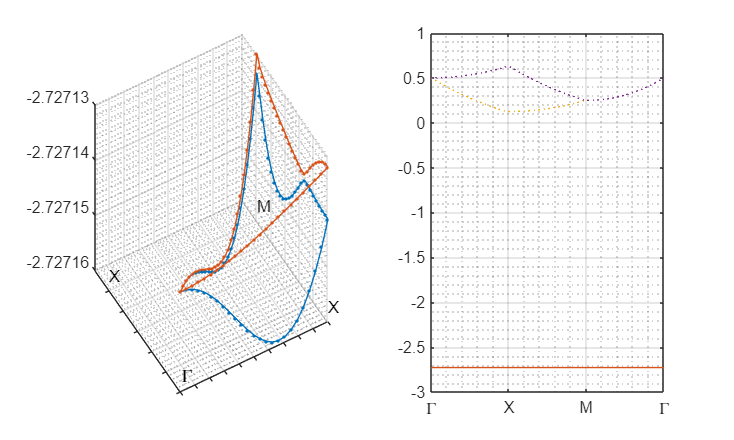

NG2 = NG1^2;
Nk2 = 3*Nk;

%	Wave vector goes from gamma to X to M to Gamma
k2 = .5*[[L; O; 1-L] [Z; L; 1-L]];

%	G = n1*b1 + n2*b2 with integer n1, n2
G2 = [Column(repmat(Column(nG), [1 NG1])) ...
	Column(repmat(Row(nG), [NG1 1]))];

U2 = -U0./sum((reshape(G2, 1, [], 2)-reshape(G2, [], 1, 2)).^2, 3);
U2(~isfinite(U2)) = 0;

E2 = zeros(Nk2, NG2);
E2a = E2;
for nk=1:Nk2
	[V, D] = eig(diag(.5*sum((k2(nk, :)-G2).^2, 2)) + U2);
	E2(nk, :) = diag(D);

	[V, D] = eig(diag(.5*sum((k2(nk, :)-G2).^2, 2)));
	E2a(nk, :) = diag(D);
end

indE = 2:3;
Emn = min(E2(:, indE), [], "all");

fig = Figure;
T = tiledlayout(fig, "Flow");

ax = nexttile(T);
plot3(ax, k2(:, 1), k2(:, 2), E2(:, indE), ".-");
grid on;
grid minor;
xticklabels([]);
yticklabels([]);
text(0, 0, Emn, "\Gamma", "VerticalAlignment", "Bottom");
text(.5, 0, Emn, "X", "VerticalAlignment", "Bottom");
text(.5, .5, Emn, "M", "VerticalAlignment", "Bottom");
text(0, .5, Emn, "X", "VerticalAlignment", "Bottom");
view(-30, 40);

ax = nexttile(T);
plot(ax, ...
	linspace(0, 3, Nk2).', E2(:, indE), ...
	linspace(0, 3, Nk2).', E2a(:, indE), ":");
xticks(0:3);
xticklabels(["\Gamma" "X" "M" "\Gamma"]);
grid on;
grid minor;

## Functions

function fig = Figure(Arg)
%	Returns handle to figure window, clears figure and sets its size & units.
arguments
	Arg.Fig = gcf;
	Arg.Width = 1000;
	Arg.Height = 600;
	Arg.Units = "Pixels";
end
fig = Arg.Fig;
clf(fig);
fig.Units = Arg.Units;
fig.Position = [10 50 Arg.Width Arg.Height];
colormap(fig, "turbo");
end
